# Calculate Basic Statistics

Instructions are in the task pane to the left. Complete and submit each task one at a time.

The handwriting samples have all been shifted so they have zero mean in both horizontal and vertical position. What other statistics could provide information about the shape of the letters? Different letters will have different distributions of points. Statistical measures that describe the shape of these distributions could be useful features.

Do not edit. This code loads and plots the data.

clear;clc
% load letterfeatures.mat
b1 = readtable("user001_B_1.txt")

b1 = 31×4 table
    Time      X        Y        P  
    ____    _____    _____    _____

    5035    0.195    0.862    0.044
    5042    0.195    0.864    0.095
    5043    0.195    0.864    0.095
    5059    0.194    0.868    0.255
    5074    0.193    0.871    0.347
    5091    0.193    0.871    0.401
    5109    0.193    0.866    0.474
    5124    0.193    0.858    0.542
    5140    0.193    0.835    0.698
    5158    0.193    0.806      0.8
    5176    0.193     0.78    0.866
    5190    0.193    0.758    0.907
    5208    0.192    0.745    0.931
    5225    0.193    0.738    0.944
    5242    0.193    0.739    0.952
    5257    0.195    0.747    0.954


b2 = readtable("user002_B_1.txt")

b2 = 137×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    11266    0.202    0.854    0.017
    11279    0.202    0.853    0.101
    11279    0.202    0.853    0.101
    11295    0.201    0.853    0.132
    11311    0.201    0.852    0.142
    11335    0.201    0.851    0.179
    11347    0.201    0.851    0.212
    11363    0.201    0.849    0.226
    11379    0.201    0.848    0.251
    11395      0.2    0.847    0.282
    11413      0.2    0.846    0.321
    11429      0.2    0.845    0.345
    11445    0.199    0.842    0.366
    11461    0.199    0.839    0.392
    11478    0.199    0.836    0.405
    11498    0.199    0.833    0.429


v1 = readtable("user001_V_1.txt")

v1 = 20×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    21842      0.2    0.226    0.011
    21848      0.2    0.227    0.081
    21848      0.2    0.227    0.081
    21866      0.2    0.229    0.382
    21883    0.199    0.229    0.522
    21898      0.2    0.227    0.685
    21915    0.201    0.219    0.819
    21932    0.203    0.205    0.966
    21950    0.206    0.185        1
    21965    0.208    0.173        1
    21982    0.211    0.159        1
    21999    0.213    0.152        1
    22017    0.216    0.154        1
    22031    0.219    0.164        1
    22048    0.222    0.179        1
    22065    0.226    0.201        1


d1 = readtable("user001_D_1.txt")

d1 = 30×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    12551    0.513    0.738    0.022
    12551    0.513     0.74    0.202
    12551    0.513     0.74    0.202
    12597    0.512    0.747    0.581
    12614     0.51    0.751    0.638
    12630    0.507    0.753    0.667
    12648    0.503    0.753    0.702
    12663    0.499    0.752    0.729
    12681    0.494    0.746    0.759
    12698    0.491    0.733    0.776
    12713     0.49    0.722    0.784
    12730    0.491    0.707     0.78
    12748    0.495    0.698    0.784
    12764    0.501    0.696    0.798
    12780    0.506    0.701    0.837
    12798    0.512    0.713    0.874


d2 = readtable("user002_D_1.txt")

d2 = 106×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    19740    0.506    0.873    0.007
    19913    0.506    0.872    0.532
    19913    0.506    0.872    0.532
    19925    0.506    0.871    0.542
    19945    0.505    0.867    0.554
    19961    0.505    0.864    0.567
    19977    0.504    0.859    0.597
    19993    0.504    0.854    0.616
    20009    0.503    0.849    0.628
    20025    0.503    0.846    0.636
    20045    0.503    0.841    0.649
    20061    0.503    0.836    0.673
    20078    0.503    0.832    0.685
    20094    0.503    0.827    0.698
    20110    0.503    0.824    0.708
    20127    0.503     0.82    0.716


m1 = readtable("user001_M_1.txt")

m1 = 28×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    34806    0.775    0.228    0.042
    34808    0.775    0.227    0.255
    34808    0.775    0.227    0.255
    34825    0.774    0.221     0.44
    34833    0.774    0.214    0.569
    34850    0.773    0.199    0.745
    34866    0.772    0.188      0.8
    34886    0.772    0.176    0.851
    34900    0.773    0.173     0.88
    34944    0.777    0.194    0.894
    34949    0.778    0.201    0.896
    34975    0.784    0.228    0.899
    34995    0.789    0.249    0.923
    35000     0.79    0.251    0.931
    35018    0.791    0.248    0.995
    35058     0.79    0.209        1


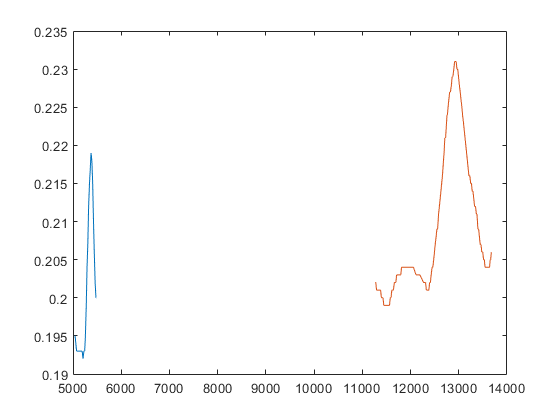

plot(b1.Time,b1.X)
hold on
plot(b2.Time,b2.X)
hold off

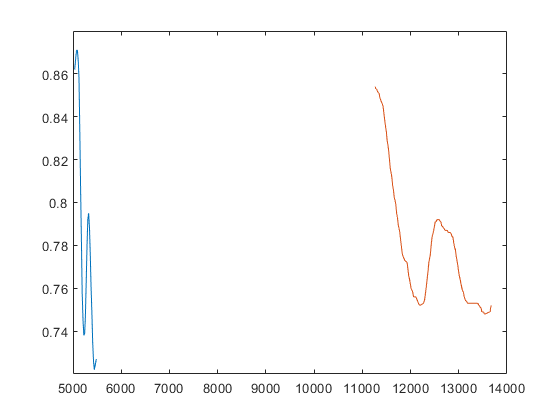

plot(b1.Time,b1.Y)
hold on
plot(b2.Time,b2.Y)
hold off

## Task 1

The MAT-file `sampleletters.mat` contains tables `b1`, `b2`, `d1`, `d2`, `m1`, `m2`, `v1`, and `v2` that hold the data for some specific examples selected from the full handwriting data set.

Use the `range` function to calculate the aspect ratio of the letter `b1` by dividing the range of values of `Y` by the range of values of `X`. Assign the result to a variable called `aratiob`.

aratiob = range(b1.Y)/range(b1.X)

aratiob = 5.5185

The letters are preprocessed to have a mean of 0 (in both `X` and `Y`). The median is less sensitive to outliers than the mean. Comparing the mean to the median can give an idea of how asymmetric a distribution is.

## Task 2

Use the `median` function to calculate the median of `b1.X` and `b1.Y`. Store the results in variables called `medxb` and `medyb`, respectively. Remember to use the `"omitnan"` flag.

medxb = median(b1.X,"omitnan")

medxb = 0.1950

medyb = median(b1.Y,"omitnan")

medyb = 0.7775

The spread of values can be measured with the mean absolute deviation (MAD), standard deviation, and variance. Each of these calculate the average of some measure of the deviation from the mean.

## Task 3

Use the `mad` function to calculate the mean absolute deviation of `b1.X` and `b1.Y`. Store the results in variables called `devxb` and `devyb`, respectively. Note that `mad` ignores NaNs by default.

devxb = mad(b1.X)

devxb = 0.0078

devyb = mad(b1.Y)

devyb = 0.0465

## Task 4

Calculate the same statistics for some other sample letters:

- The aspect ratio of `v1`, stored in `aratiov`

- The median of `d1.X`, stored in `medxd`

- The median of `d1.Y`, stored in `medyd`

- The mean absolute deviation of `m1.X`, stored in `devxm`

- The mean absolute deviation of `m1.Y`, stored in `devym`

aratiov = range(v1.Y)/range(v1.X)

aratiov = 2.4063

medxd = median(d1.X,"omitnan")

medxd = 0.5130

medyd = median(d1.Y,"omitnan")

medyd = 0.7460

devxm = mad(m1.X)

devxm = 0.0139

devym = mad(m1.Y)

devym = 0.0190

## Further Practice

How do the values compare for different letters? Will these statistics be useful features? Try calculating the same statistics for a second sample of the same letters (`b2`, `d2`, `m2`, and `v2`).

This plot shows the aspect ratio and MAD of the horizontal position of the eight letter samples:

https://matlabacademy-content.mathworks.com/4.13/R2019b/content/Machine%20Learning/Engineering%20Features/Calculating%20Summary%20Statistics/Images/lettergroups.png

As you might expect, the letter b is tall, while m is wide. The letters m and v are more spread horizontally than b and d.

You might want to visualize the samples to see why d has a lower aspect ratio than b:

`plot``(``b1.X``,``b1.Y``,``b2.X``,``b2.Y``)`

`axis``([``-1` `1` `-1` `1``])`

`axis` `equal`

`plot``(``d1.X``,``d1.Y``,``d2.X``,``d2.Y``)`

`axis``([``-1` `1` `-1` `1``])`

`axis` `equal`

What else can distinguish between b and d? Look at the values of the median horizontal position.

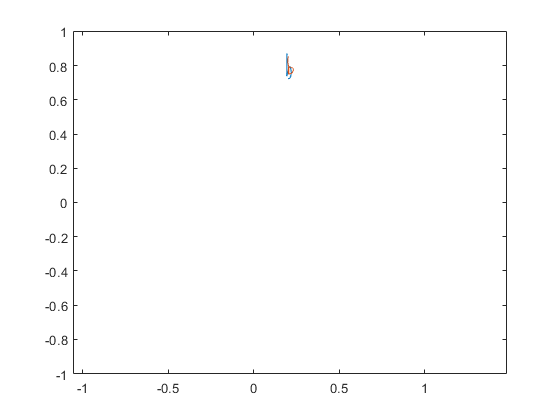

plot(b1.X,b1.Y,b2.X,b2.Y)
axis([-1 1 -1 1])
axis equal

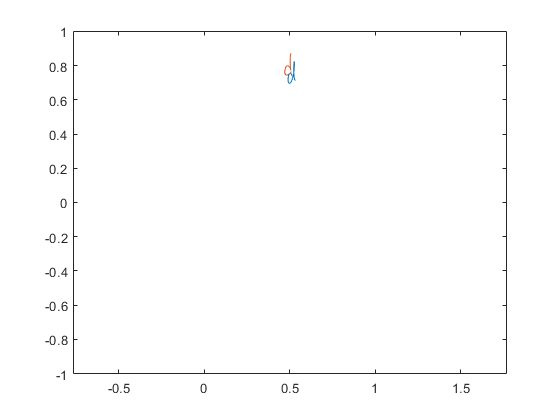

plot(d1.X,d1.Y,d2.X,d2.Y)
axis([-1 1 -1 1])
axis equal